# Example 1: executing a simulation 

### This assumes the database and default data has been set up

## 1. add directory contents to exec path, connect to db


% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), filesep);
idx = find(strcmp(file_path, 'uavtestbed'));
root_directory = strjoin(file_path(1:idx), filesep);
% switch to the root directory
cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% load the api
api = jsondecode(fileread('sql/api.json'));

% username=input('username: ', 's');
% password=input('password: ', 's');
username = 'macslab';
password = 'Ch0colate!';
db_name = 'uav2_db';
%the database connection
% conn = postgresql(username, password, "Server", 'localhost', "PortNumber", 5432, "DatabaseName", 'uav2_db');
conn = database(db_name, username, password);

## 2. Retrieve UAV and basic info from db

- flight num / flight id

- last timestamp

- stop codes and group ids

% check out what UAVs are in the db
uav_tb = select(conn, api.matlab.assets.LOAD_ALL_UAVS)
% load the UAV 
% note, the default UAV is not supported any more and some functionality
% below will be skipped if using the default uav (recommended to use the tarot)
serial_number = char(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).serial_number);
serial_number = string(serial_number(1,:));
version = max(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).version);
uav_tb = select(conn, eval(api.matlab.assets.LOAD_UAV_BY_SERIAL));
uav_tb
%uav_tb.escs_id = str2double(strsplit(erase(char(uav_tb.escs_id{1}), ["{", "}", "'"]), ','))
uav = load_uav(conn, serial_number, version, api);

% uav = load('params/uav.mat').uav;
uav

### Load the stop_code_tb and group_tb

% to match stop codes with the simulation
% new stop codes for your specific experiment can be created
stop_code_tb = select(conn, "select * from stop_code_tb;")
% for organizing multiple executions
group_id_tb = select(conn, "select * from group_tb")
group_id = group_id_tb.id(1);

### Look at the flight summary table and get the last timestamp and flight_id

- since these are simulations, the simulation time will grow beyond real time so we cannot just use " datestr(now) " as the start time

- The start time is important because the telemetry data is indexed via timestamp

- the start and stop timestamps in the flight_summary_tb are used to access the flight telemetry data for that flight

- the flight_id refers to the id field of flight_summary_tb

% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from session_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second')
% get the flight_id (the unique id in the data table)
flight_id = table2array(select(conn, 'select id from session_tb order by id desc limit 1;')) + 1
if isempty(flight_id)
    flight_id = 1;
end

% the flight number of the selected uav (i.e. how many flights it has gone
% previously + 1 for the upcomming flight)
flight_num = table2array(select(conn, sprintf('select flight_num from session_tb where uav_id = %d order by dt_start desc limit 1;', uav.id))) + 1;
if isempty(flight_num)
    flight_num = 1;
end

- clear the table (the data is in the uav struct now)

clear('uav_tb');

## 3. Load the trajectory

% load the trajectory information
trajectory_tb = readtable('trajectories/trajectories_exported.csv');
trajectory_tb = trajectory_tb(trajectory_tb.path_time < uav.max_flight_time * .6, :);
trajectory_tb = trajectory_tb(trajectory_tb.path_time > uav.max_flight_time *.6 - 1.5, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')
trajectory = get_trajectory(trajectory_tb, randi(height(trajectory_tb)))

### Plot the trajectory

f2 = figure(2); clf;
f2.Position = [0 0 600 600];
map = load(sprintf('trajectories/%s.mat', trajectory.map)).(sprintf('%s', trajectory.map));
hold on;
show(map);
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(trajectory.path)-1
    plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")
clear('map', 'i', 'f2');

## 4. Setup simulation params

% stop measure on the simulation, in general it should stop before this
sim_params.max_sim_time = 4000;

% performance thresholds %%%% max_pos_err calculation is incorrect (does
% not account for time offset, needs updated)
sim_params.perf_param_thresh.max_pos_err  = 3.5; % this is check in the simulation
sim_params.perf_param_thresh.min_soc      = .2; % this is check in the simulation
sim_params.perf_param_thresh.min_v        = uav.battery.EOD * 1.15; % this is checked in the simulation
sim_params.perf_param_thresh.min_soh_batt = uav.battery.Q * .6; % this is checked after %% can this even be done?
sim_params.perf_param_thresh.avg_pos_err  = 2; % this is checked after
sim_params.perf_param_thresh.max_pos_err_var  = 1; % check this (currently not used)
% sim_params.z_ref = 8;


% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;
sim_params.initial_conditions  = load('params/initial_conditions.mat').IC;
% sim_params.initial_conditions.Z = 0;
sim_params.z_ref = sim_params.initial_conditions.z_ref;

sim_params.battery_estimator   = load('estimation/batteryestimator').batteryestimator;
sim_params.battery_estimator.Qinit = uav.battery.Q;
if uav.battery.v0 < 4.3
    sim_params.battery_estimator.soc_ocv = interp1([sim_params.battery_estimator.soc_ocv(1) sim_params.battery_estimator.soc_ocv(end)], [3.04 4.2], sim_params.battery_estimator.soc_ocv);
end

if strcmp(uav.uav.common_name, 'default')
    sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
    sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;
end

sim_params.initial_conditions.X = trajectory.start(1);
sim_params.initial_conditions.Y = trajectory.start(2);

**Replanning test work**

map = load('map.mat').map;
H = load('distance_matrix.mat').H;
waypoints = load('waypoints.mat').waypoints;
p = 15;
current_location = [waypoints(p,1), waypoints(p,2)]
f1 = figure(1); clf;
hold on;
show(map);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3, 'DisplayName', sprintf("p%d", i)); 
end
plot(current_location(1), current_location(2), 'x', 'MarkerFaceColor', 'red', 'markersize', 17, 'LineWidth', 5, 'DisplayName', sprintf("p%d", i)); 
hold off;


## 5. Load process data

- environment (wind)

- degradation (battery, motors)

- Note, the tarot already has default processes linked!

process_type = 'degradation';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))
%%%%% get the battery degradation functions
for i = 1:length(uav.battery.process_id)
    params = process_tb(process_tb.id_1 == uav.battery.process_id(i), 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.battery.(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end
%%%%% get the motor degradation function
for j = 1:length(uav.motors)
    params = process_tb(process_tb.id_1 == uav.motors(j).process_id(1), 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.motors(j).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end
%%%%% get the esc failure probability function
process_type = 'failure probability';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))
for j = 1:length(uav.escs)
    params = process_tb(process_tb.id_1 == uav.escs(j).process_id, 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.escs(j).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end

process_type = 'environment';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))  
i = randi(height(process_tb));
params = process_tb(i, 'parameters').parameters{1}
res = jsondecode(string(params));
fn = fieldnames(res);
for j = 1:length(fn)
    processes.(sprintf("%s", process_type)).(sprintf("%s", process_tb(i, 'subtype').subtype{1})).(sprintf("%s", process_tb(i, 'subtype2').subtype2{1})).(sprintf("%s", fn{j})) = res.(fn{j})
end

clear('description', 'i', 'params', 'j', 'proc_tb', 'process_tb', 'process_type', 'res', 'fn');
%%%%%%%%%%%%%%%%%%% get probability of motor failure

P_failure = zeros(length(uav.escs), 1);
for i=1:length(uav.motors)
    %% give motors random age between 0 and 8000 amp hours
    % uav.motors(i).age = rand*4000;
    pf = get_failure_prob(uav.escs(i).age, uav.escs(i).e_coef);
    P_failure(i) = pf;
end
P_failure

## 5. Simulate

tic
%if strcmp(uav.uav.common_name, 'tarot t18 uav')
sim('simulink/uav_simulation_tarot.slx');    
%sim('simulink/tarot_replanning.slx');
%else 
%    sim('simulink/uav_simulation.slx');
%end
toc


find(any(escs.esc_faults.Data), 1)


ans =

  1×0 empty double row vector



% old_ct = zeros(length(uav.motors),1);

for i = 1:length(uav.motors)
    % old_ct(i) = uav.motors(i).ct;
    % uav.motors(i).ct = 1.5 * uav.motors(i).ct;
    uav.motors(i).cq = uav.motors(i).cq * .75;
end

#### calculate dt_stop

dt_stop = dt_start + minutes(time.Data(end, 1))

dt_stop = datetime
   02-Oct-2022 20:57:49


## 5a. check stop codes and system performance parameter thresholds

- stop codes 1-4 are checked in simulation, 5-6 are checked after

stop_code = max(find(any(stop_codes.Data(:,:))))

stop_code = 4

string(stop_code_tb.description(stop_code_tb.id==stop_code))

ans = "arrival success"

#### check the average position error threshold

if mean(errors.euclidean_pos_err.Data) > sim_params.perf_param_thresh.avg_pos_err
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'average position error'))
end

#### (move to preflight: check the minimum state of health for the battery threshold - battery.Q)

if  uav.battery.Q < sim_params.perf_param_thresh.min_soh_batt
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'low soh (battery)'))
end

## 6. Update component degradation parameters

- battery

if strcmp(string(uav.uav.common_name), "tarot t18 uav")
    %uav.battery.age = 0;
    avg_current = abs(mean(battery.battery_true.i.Data(:)));
    flight_time = time.Data(end)/60; % this is in minutes
    amp_hours = avg_current * flight_time;
    uav.battery.age = uav.battery.age + amp_hours;

- [TODO] implement estimators and pull covariance instead of "factory" 2% 

    Q_mu = polyval(uav.battery.q_coef, uav.battery.age);
    Q_std = .02*Q_mu;
    
    R0_mu = polyval(uav.battery.r_coef, uav.battery.age);
    R0_std = .02*R0_mu;
    
    uav.battery.Q = normrnd(Q_mu, Q_std);
    uav.battery.R0 = normrnd(R0_mu, R0_std);

charge =   Simulink.SimulationOutput:

     battery_state_params: [1x1 struct] 
                     time: [1x1 timeseries] 
                     tout: [24480x1 double] 
                        u: [1x1 timeseries] 

       SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
             ErrorMessage: [0x0 char] 


- motors

    for i = 1:length(uav.motors)
        %uav.motors(i).age = 0;
        avg_current = abs(mean(motors.(sprintf('m%d',i)).current.Data(:)));
        uav.motors(i).age = uav.motors(i).age + avg_current * flight_time;
        m_mu = polyval(uav.motors(i).r_coef, uav.motors(i).age);
        m_std = .02*m_mu;
        uav.motors(i).Req = normrnd(m_mu, m_std);
    end
end

- the uav

%uav.uav.age = 0;
uav.uav.age = uav.uav.age + amp_hours;

## 6a. charge the battery

persist the battery state

uav.battery.v = battery.battery_true.v.Data(end);
uav.battery.z = battery.battery_true.z.Data(end);

standard charging practice is 1C

u = -22; %-uav.battery.Q;  % Q degrades but u should remain the factory value of 22 for the case of the tarot
charge = sim('continuous_battery.slx')
uav.battery.v = charge.battery_state_params.v.Data(end);
uav.battery.z = charge.battery_state_params.z.Data(end);
avg_current = abs(mean(charge.u.Data));
charge_time = charge.time.Data(end)/3600; % this is in seconds
amp_hours = avg_current * charge_time;
charge_discount = .9;
uav.battery.age = uav.battery.age + (amp_hours * charge_discount);

### Update degradation parameters

- charging the battery doesnt degrade it as much as discharging

Q_mu = polyval(uav.battery.q_coef, uav.battery.age);
Q_std = .02*Q_mu;

R0_mu = polyval(uav.battery.r_coef, uav.battery.age);
R0_std = .02*R0_mu;
uav.battery.Q = normrnd(Q_mu, Q_std);
uav.battery.R0 = normrnd(R0_mu, R0_std);

- **update parameters in the database**

execute(conn, eval(api.matlab.components.UPDATE_BATTERY_PARAMETERS));
for i = 1:length(uav.motors)
    execute(conn, eval(api.matlab.components.UPDATE_MOTOR_PARAMETERS));
end

## 7. Update the asset age in the database 

% conn = db_connect('nasadb');

var_names = 1×31 string array
    "id"    "stop_code"    "z_start"    "z_end"    "v_start"    "v_end"    "m1_avg_current"    "m2_avg_current"    "m3_avg_current"    "m4_avg_current"    "m5_avg_current"    "m6_avg_current"    "m7_avg_current"    "m8_avg_current"    "avg_pos_err"    "max_pos_err"    "std_pos_err"    "avg_ctrl_err"    "max_ctrl_err"    "std_ctrl_err"    "distance"    "flight_time"    "avg_current"    "amp_hours"    "dt_start"    "dt_stop"    "trajectory_id"    "uav_id"    "uav_version"    "flight_num"    "group_id"


conn = database(db_name, username, password);

execute(conn, eval(api.matlab.assets.UPDATE_BATTERY_AGE));
execute(conn, eval(api.matlab.assets.UPDATE_UAV_AGE));
for i = 1:length(uav.motors)
    execute(conn, eval(api.matlab.assets.UPDATE_MOTOR_AGE))
end
clear('charge', 'avg_current', 'charge_time', 'amp_hours', 'Q_mu', 'Q_std', 'R0_mu', 'R0_std', 'm_mu', 'm_std', 'u', 'flight_time');

flight_summary_tb = 1×30 table
    stop_code    z_start     z_end     v_start    v_end     m1_avg_current    m2_avg_current    m3_avg_current    m4_avg_current    m5_avg_current    m6_avg_current    m7_avg_current    m8_avg_current    avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours          dt_start                dt_stop           trajectory_id    uav_id    uav_version    flight_num    group_id

## 8. Insert summary data into the db

% get the variable names, but note "id" isn't used
var_names = get_column_names(conn, 'session_tb')

flight_summary_tb = table(max(find(any(stop_codes.Data(:,:)))), ...

var_names = 1×22 string array
    "id"    "flight_id"    "q_deg"    "q_var"    "r_deg"    "r_var"    "m1_deg"    "m1_var"    "m2_deg"    "m2_var"    "m3_deg"    "m3_var"    "m4_deg"    "m4_var"    "m5_deg"    "m5_var"    "m6_deg"    "m6_var"    "m7_deg"    "m7_var"    "m8_deg"    "m8_var"


                          battery.battery_true.z.Data(1), ...
                          battery.battery_true.z.Data(end), ...

var_names = 1×11 cell array
    {'flight_id'}    {'q_deg'}    {'r_deg'}    {'m1_deg'}    {'m2_deg'}    {'m3_deg'}    {'m4_deg'}    {'m5_deg'}    {'m6_deg'}    {'m7_deg'}    {'m8_deg'}


                          battery.battery_true.v.Data(1), ...
                          battery.battery_true.v.Data(end), ...
                          mean(motors.m1.current), ...
                          mean(motors.m2.current), ...
                          mean(motors.m3.current), ...
                          mean(motors.m4.current), ...
                          mean(motors.m5.current), ...
                          mean(motors.m6.current), ...
                          mean(motors.m7.current), ...
                          mean(motors.m8.current), ...
                          mean(errors.euclidean_pos_err), ...
                          max(errors.euclidean_pos_err), ...

flight_degradation_tb = 1×11 table
    flight_id    q_deg       r_deg      m1_deg     m2_deg     m3_deg     m4_deg     m5_deg     m6_deg     m7_deg     m8_deg 
    _________    ______    _________    _______    _______    _______    _______    _______    _______    _______    _______

        1        21.215    0.0014482    0.26613    0.26588    0.27051    0.25129    0.27231    0.27376    0.25761    0.26858


                          std(errors.euclidean_pos_err), ...
                          mean(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          max(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          std(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          round(calculatedistance([position.true.Data(:,1) position.true.Data(:,2)]), 4), ...
                          time.Time(end)/60, ...
                          mean(battery.battery_true.i.Data), ...
                          mean(battery.battery_true.i.Data)*time.Time(end)/60/60, ...
                          dt_start, ...
                          dt_start + minutes(time.Time(end)/60), ...

ans = 40.0035

                          trajectory.id, ...
                          uav.id, ...
                          uav.version, ...

ans = 40.0000

                          flight_num, ...
                          group_id, ...
                          'VariableNames',  cellstr(var_names(1,2:end)))

ans = 40.0035

% write the data to the database
sqlwrite(conn, 'session_tb', flight_summary_tb);

## 9. Get the degradation data and insert it

% get var names [DEPRECIATED - see new table definition]
var_names = get_column_names(conn, 'degradation_tb')

var_names = {'flight_id' 'q_deg' 'r_deg' 'm1_deg' 'm2_deg' 'm3_deg' 'm4_deg' 'm5_deg' 'm6_deg' 'm7_deg' 'm8_deg'}

battery_tt = 861×9 timetable
     Time     battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var
    ______    ______________    ______________    ______________    ______________    _____________    _____________    _____________    _________________    _________________

    0 sec           22.2                 1          0.0011038          0.70206             22.2                 1            0.0011                 0                 0.003    
    1 sec         22.113           0.99921          0.0011233       

flight_degradation_tb = table(flight_id, ...
                              uav.battery.Q, ...
                              uav.battery.R0, ...
                              uav.motors(1).Req, ...
                              uav.motors(2).Req, ...
                              uav.motors(3).Req, ...
                              uav.motors(4).Req, ...

errors_tt = 861×5 timetable
     Time     euclidean_pos_err    x_pos_err    y_pos_err    x_ctrl_err    y_ctrl_err
    ______    _________________    _________    _________    __________    __________

    0 sec           0.1725           0.10823      0.13432     -0.21576       -0.5011 
    1 sec          0.28321         -0.028013     -0.28182      0.24135      0.095072 
    2 sec           1.1352           -1.1235     -0.16237       1.0881       0.22387 
    3 sec           1.7298           -1.7277    -0.085204       1.6448      0.015516 
    4 sec           1.6388           -1.6267     -0.19945       1.6869       0.33918 
    5 sec           1.5964           -1.5651     -0.31432      

                              uav.motors(5).Req, ...
                              uav.motors(6).Req, ...
                              uav.motors(7).Req, ...
                              uav.motors(8).Req, ...
                              'VariableNames', var_names)
clear('var_names');

environment_tt = 861×3 timetable
     Time     wind_gust_x    wind_gust_y    wind_gust_z
    ______    ___________    ___________    ___________

    0 sec          2.539        0.61969        0.93678 
    1 sec         1.6669         1.9036        0.59645 
    2 sec         2.7588       -0.40135        0.24748 
    3 sec           1.04          2.099        0.42238 
    4 sec      -0.010902         1.9341       -0.24051 
    5 sec         1.9859     -0.0055669         1.2727 
    6 sec         2.0148        0.30334        0.23735 
    7 sec         2.1797         4.0761         1.3366 
    8 sec      -0.035476         1.8512        0.36701 
    9 sec         1.6424       -0.35225     

% write the data to the database
sqlwrite(conn, 'degradation_tb', flight_degradation_tb);

motors_tt = 861×32 timetable
     Time     m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    m5_torque    m5_current    m5_vref    m6_rpm    m6_torque    m6_current    m6_vref    m7_rpm    m7_torque    m7_current    m7_vref    m8_rpm    m8_torque    m8_current    m8_vref
    ___

## 10. Get the telemetry data

#### There are multiple different sample rates

- The battery is sampled at 1hz

t_batt = battery.battery_true.v.Time;
1/mean(diff(t_batt))

- airframe dynamics at 40hz

t_dynamics = errors.ctrl_err.x_error.Time;
1/mean(diff(t_dynamics))

- Other variables step with the simulation

- That small difference needs accounted for!

t_sim = time.Time;
1/mean(diff(t_sim))
clear('t_batt', 't_dynamics', 't_sim');

### Battery data

sample_rate = 1;

position_tt = 861×6 timetable
     Time     x_pos_gps    y_pos_gps    z_pos_gps    x_pos_true    y_pos_true    z_pos_true
    ______    _________    _________    _________    __________    __________    __________

    0 sec      50.108       25.367       2.5482            50            25             3  
    1 sec      49.563       25.347       3.2208        49.777        25.161        3.1507  
    2 sec      48.629       25.795       3.1396        48.594        25.857         3.166  
    3 sec      48.086       26.708       3.1791        48.003        26.639        3.1092  
    4 sec      48.152       27.211       3.2066        48.212        27.351          3.04  
  


battery_tt = sync_telemetry_data(battery, sample_rate, time.Time(:))

### Errors data

errors_tt = sync_telemetry_data(errors, sample_rate, time.Time(:));
errors_tt.Properties.VariableNames{'pos_err_x_pos_err'} = 'x_pos_err';
errors_tt.Properties.VariableNames{'pos_err_y_pos_err'} = 'y_pos_err';
errors_tt.Properties.VariableNames{'ctrl_err_x_error'}  = 'x_ctrl_err';
errors_tt.Properties.VariableNames{'ctrl_err_y_error'}  = 'y_ctrl_err';
errors_tt

### Environment data

environment_tt = sync_telemetry_data(environment, sample_rate, time.Time(:));

velocity_tt = 861×6 timetable
     Time     x_vel_gps    y_vel_gps    z_vel_gps    x_vel_true    y_vel_true    z_vel_true
    ______    _________    _________    _________    __________    __________    __________

    0 sec     0.0086217    0.0031877    -0.013077            0            0              0 
    1 sec      -0.80965      0.44184     0.049961     -0.80936      0.44001       0.065612 
    2 sec       -1.1339      0.88703    -0.017729      -1.1399      0.87656      -0.015749 
    3 sec     -0.063627       0.6747    -0.091285    -0.056335      0.67143      -0.086136 
    4 sec       0.34371      0.79975    -0.041688      0.35066      0.80437      -0.050524 
  

environment_tt.Properties.VariableNames{'wind_gust-1'}  = 'wind_gust_x';
environment_tt.Properties.VariableNames{'wind_gust-2'}  = 'wind_gust_y';
environment_tt.Properties.VariableNames{'wind_gust-3'}  = 'wind_gust_z';
environment_tt

### Motor data

motors_tt = sync_telemetry_data(motors, sample_rate, time.Time(:))

flight_telemetry_tb = 861×61 timetable
      dt      battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    m5_torque

### Position data

position_tt = sync_telemetry_data(position, sample_rate, time.Time(:));
position_tt.Properties.VariableNames{'gps-1'}  = 'x_pos_gps';
position_tt.Properties.VariableNames{'gps-2'}  = 'y_pos_gps';
position_tt.Properties.VariableNames{'gps-3'}  = 'z_pos_gps';

flight_telemetry_tb = 861×61 timetable
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    

position_tt.Properties.VariableNames{'true-1'}  = 'x_pos_true';
position_tt.Properties.VariableNames{'true-2'}  = 'y_pos_true';
position_tt.Properties.VariableNames{'true-3'}  = 'z_pos_true';
position_tt

### Velocity data

velocity_tt = sync_telemetry_data(velocity, sample_rate, time.Time(:));
velocity_tt.Properties.VariableNames{'gps-1'}  = 'x_vel_gps';
velocity_tt.Properties.VariableNames{'gps-2'}  = 'y_vel_gps';
velocity_tt.Properties.VariableNames{'gps-3'}  = 'z_vel_gps';
velocity_tt.Properties.VariableNames{'true-1'}  = 'x_vel_true';
velocity_tt.Properties.VariableNames{'true-2'}  = 'y_vel_true';
velocity_tt.Properties.VariableNames{'true-3'}  = 'z_vel_true';
velocity_tt

### **Merge the timetables**

flight_telemetry_tb = [battery_tt environment_tt motors_tt errors_tt position_tt velocity_tt];
clear('battery_tt', 'environment_tt', 'motors_tt', 'errors_tt', 'position_tt', 'velocity_tt');
flight_telemetry_tb.Properties.DimensionNames{1} = 'dt';
flight_telemetry_tb

### Convert the time vector duration to a datetime

dt_start.Format = 'MM-dd-uuuu HH:mm:ss.SSS';


idx_v =

  0×1 empty double column vector



dt_stop.Format = 'MM-dd-uuuu HH:mm:ss.SSS';


idx_z =

  0×1 empty double column vector



time_vec = datetime([dt_start: seconds(1/sample_rate) : dt_stop]');


idx_i =

  0×1 empty double column vector



flight_telemetry_tb.dt = time_vec

### Impute any missing values

- Usually this isn't required, but there are edge cases

missing_v = sum(ismissing(flight_telemetry_tb.battery_true_v));

flight_telemetry_tb = 861×63 table
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    m5_t

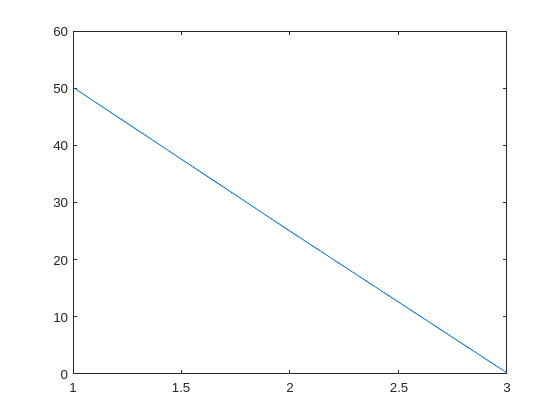

missing_z = sum(ismissing(flight_telemetry_tb.battery_true_z));
missing_i = sum(ismissing(flight_telemetry_tb.battery_true_i));
vals_v = flight_telemetry_tb.battery_true_v;
vals_z = flight_telemetry_tb.battery_true_z;
vals_i = flight_telemetry_tb.battery_true_i;
poly_v = polyfit(1:1:length(vals_v), vals_v, 4);
poly_z = polyfit(1:1:length(vals_z), vals_z, 4);
poly_i = polyfit(1:1:length(vals_i), vals_i, 4);
missing_vals_v = zeros(1, missing_v);
missing_vals_z = zeros(1, missing_z);
missing_vals_i = zeros(1, missing_i);
for i = 1:missing_v
    missing_vals_v(1,i) = polyval(poly_v, i);
    missing_vals_z(1,i) = polyval(poly_z, i);
    missing_vals_i(1,i) = polyval(poly_i, i);
end

idx_v = find(ismissing(flight_telemetry_tb.battery_true_v))
idx_z = find(ismissing(flight_telemetry_tb.battery_true_z))

idx_i = find(ismissing(flight_telemetry_tb.battery_true_i))
flight_telemetry_tb.flight_id = repmat(flight_id, height(flight_telemetry_tb), 1);
% for i = 1:length(idx_z)
%     flight_telemetry_tb.battery_true_v(idx_z(i)) = polyval(poly_v, 20+i);
%     flight_telemetry_tb.battery_true_z(idx_z(i)) = polyval(poly_z, 20+i);
%     flight_telemetry_tb.battery_true_i(idx_z(i)) = polyval(poly_i, 20+i);
% end
flight_telemetry_tb = timetable2table(flight_telemetry_tb)

### Insert the telemetry data into the database

% write the data to the database
sqlwrite(conn, 'telemetry_tb', flight_telemetry_tb);
clear('missing_v', 'missing_z', 'missing_i', 'x', 'vals_v', 'vals_z', 'vals_i', 'poly_v', 'poly_z', 'poly_i', 'missing_vals_v', 'missing_vals_z', 'missing_vals_i', 'idx_v', 'idx_z', 'idx_i', 'dt_start', 'dt_stop', 'time_vec', 'environment', 'errors', 'flight_degradation_tb', 'flight_summary_tb', 'motors', 'position', 'stop_codes', 'time', 'tout', 'velocity', 'i', 'stop_code', 'trajectory', 'battery');

%% TIM HERE (for using process_id from uav_tb)
% save as char
% load and parse char



% Convert to JSON text
jsonText2 = jsonencode(api);
% Write to a json file
fid = fopen('api.json', 'w');
fprintf(fid, '%s', jsonText2);
fclose(fid);

plot(position.gps.Data(3,:))